Constants

raw_filename = "bitcoin.csv";
train_filename = "test_data/bitcoin_train.csv";
test_filename = "test_data/bitcoin_test.csv";

Load data

trainData = readtable(train_filename, MissingRule="error", ExpectedNumVariables=5, ExtraColumnsRule="error", DecimalSeparator=",");
testData = readtable(test_filename, MissingRule="error", ExpectedNumVariables=5, ExtraColumnsRule="error", DecimalSeparator=",");

trainData = table2timetable(trainData);
testData = table2timetable(testData);

Let's plot the data

highlow(trainData)

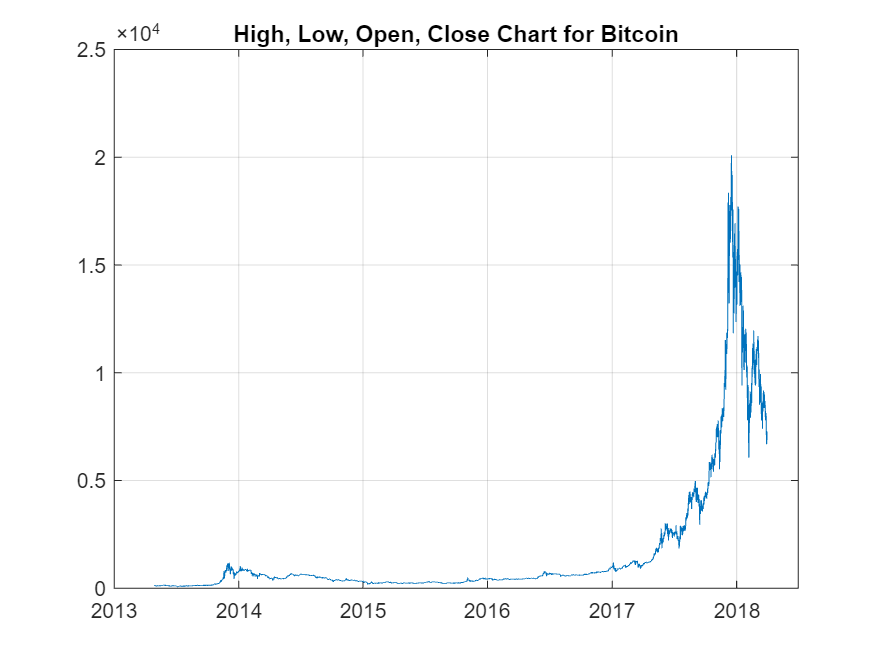

title('High, Low, Open, Close Chart for Bitcoin')

highlow(testData)

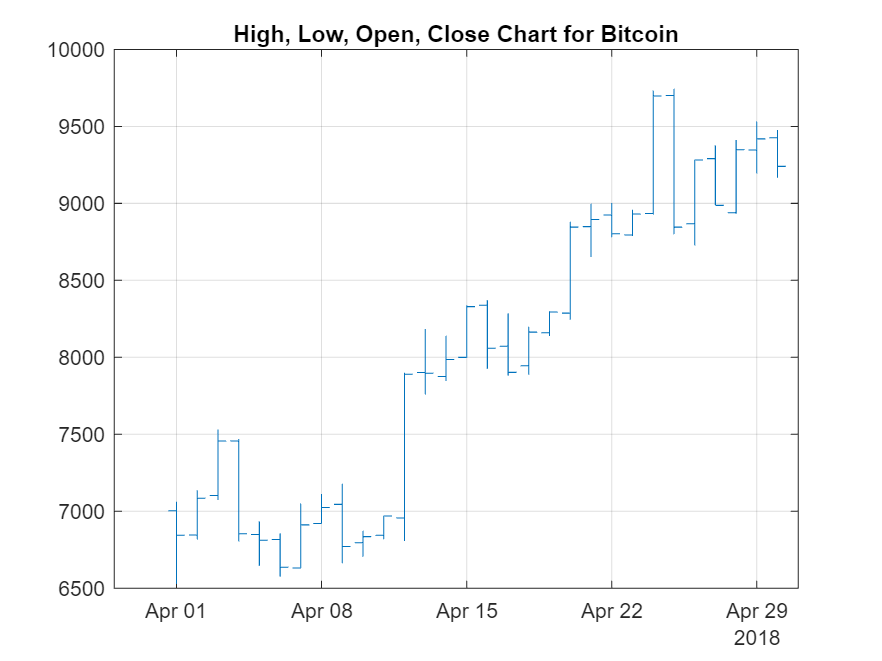

title('High, Low, Open, Close Chart for Bitcoin')

Let's test our strategy

Day 1: Portfolio value = 5.0000 BTC
Day 2: Portfolio value = 4.9978 BTC
Day 3: Portfolio value = 5.0175 BTC
Day 4: Portfolio value = 5.0161 BTC
Day 5: Portfolio value = 5.0503 BTC
Day 6: Portfolio value = 4.9896 BTC
Day 7: Portfolio value = 4.9752 BTC
Day 8: Portfolio value = 5.1081 BTC
Day 9: Portfolio value = 5.1024 BTC
Day 10: Portfolio value = 5.1260 BTC
Day 11: Portfolio value = 5.2297 BTC
Day 12: Portfolio value = 5.3828 BTC
Day 13: Portfolio value = 5.4701 BTC
Day 14: Portfolio value = 5.4483 BTC
Day 15: Portfolio value = 5.4142 BTC
Day 16: Portfolio value = 5.4032 BTC
Day 17: Portfolio value = 5.5015 BTC
Day 18: Portfolio value = 5.5144 BTC
Day 19: Portfolio value = 5.9151 BTC
Day 20: Portfolio value = 6.2647 BTC
Day 21: Portfolio value = 6.3520 BTC
Day 22: Portfolio value = 6.2414 BTC
Day 23: Portfolio value = 6.1630 BTC
Day 24: Portfolio value = 6.3095 BTC
Day 25: Portfolio value = 6.4189 BTC
Day 26: Portfolio value = 6.3537 BTC
Day 27: Portfolio value = 6.0600 BTC
Day 28: Po

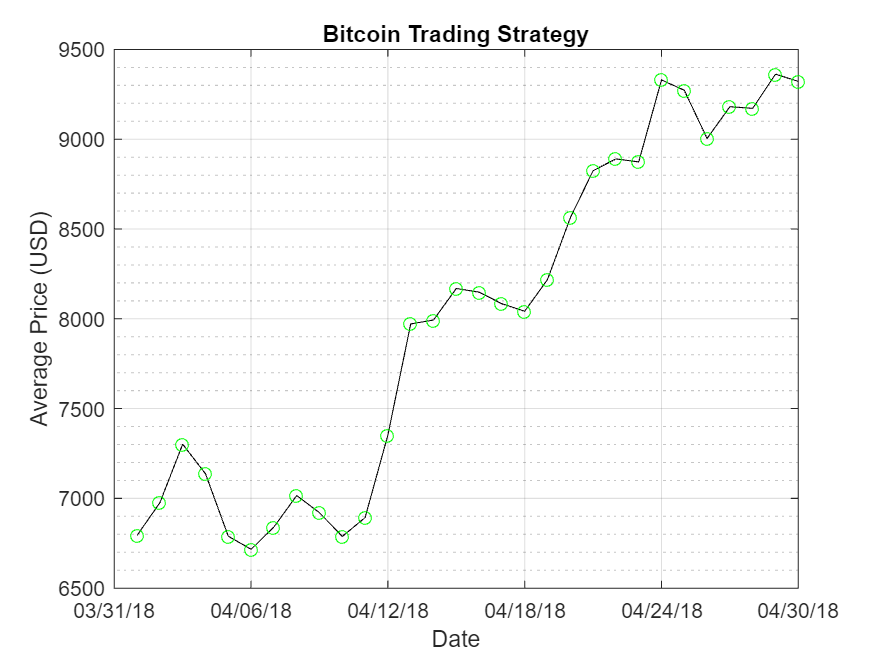

ans = 6.3541

raport(train_filename, test_filename)

full_data = readtable(raw_filename, MissingRule="error", ExpectedNumVariables=5, ExtraColumnsRule="error", DecimalSeparator=",");